%clearing all the previous outputs
clc
clear
% M = 1000Kg, m1 = m2 = 100Kg, l1 = 20m and l2 = 10m substitute in A&B and then calculate controllability matrix
M_val = 1000;
m1_val = 100;
m2_val = 100;
l1_val = 20;
l2_val = 10;
g_val = 9.81;

%Linearized equations
A = [0 1 0 0 0 0;
    0 0 (-g_val*m1_val)/M_val 0 (-g_val*m2_val)/M_val 0;
    0 0 0 1 0 0;
    0 0 -(g_val*(M_val+m1_val))/(M_val*l1_val) 0 -(g_val*m2_val)/(M_val*l1_val) 0;
    0 0 0 0 0 1;
    0 0 -(g_val*m1_val)/(M_val*l2_val) 0 -(g_val*(M_val+m2_val))/(M_val*l2_val) 0];
B = [0;
    1/M_val;
    0;
    1/(M_val*l1_val);
    0;
    1/(M_val*l2_val)];

C_01 = [1 0 0 0 0 0];

C_02 = [0 0 1 0 0 0;   
    0 0 0 0 1 0];

C_03 = [1 0 0 0 0 0;
    0 0 0 0 1 0];

C_04 = [1 0 0 0 0 0;  
    0 0 1 0 0 0;   
    0 0 0 0 1 0];
D = 0;


Q = [1000 0 0 0 0 0;  %x penalize
     0 1000 0 0 0 0;  %x_dot penalize
     0 0 1 0 0 0;   %theta1 penalize
     0 0 0 1 0 0;   %theta1_dot penalize
     0 0 0 0 1 0;   %theta2 penalize
     0 0 0 0 0 1];  %theta2_dot penalize
R=0.001;

Defining the system before using the observer

sys1 = ss(A,B,C_01,D);
sys2 = ss(A,B,C_02,D);
sys3 = ss(A,B,C_03,D);
sys4 = ss(A,B,C_04,D);

Finding L

p = [-1; -2; -3; -4; -5; -6];
L1 = place(A',C_01',p)';
disp(L1);

   1.0e+03 *

    0.0210
    0.1734
   -2.9262
    0.0805
    2.2116
   -1.4493



L3 = place(A',C_03',p)';
disp(L3);

   13.0744   -0.8244
   56.2562   -8.4805
  -89.0764   19.7693
  -20.0115   10.9419
    0.3520    7.9256
    3.4793   13.2122



L4 = place(A',C_04',p)';
disp(L4);

    8.5631   -0.8851    0.0000
   17.5219   -4.9484   -0.9810
   -0.9140    9.4369   -0.0000
   -4.1173   20.9385   -0.0491
    0.0000   -0.0000    3.0000
    0.0000   -0.0981    0.9209



[K,~,~] = lqr(A, B, Q, R);
disp(K);

   1.0e+03 *

    1.0000    1.8191   -0.2725   -0.9704   -0.1740   -0.5649



System with Luenberger Non Linear 

L_poles = [-4; -4.5; -5; -5.5; -6; -6.5];
% Specifying the initial condition where estimated states 
% are initialized to zero
x0 = [0;0;10;0;20;0;0;0;0;0;0;0];


% The Luenberger observer obtained when x(t) is observed
% The initial condition
x0_obs = [10;0;10;0;20;0];

t_span = 0:0.01:10000;

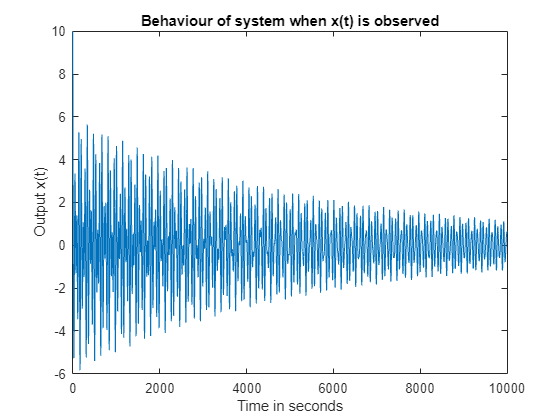

% Plotting x(t) for non-linear system when x(t) is observed
[ts,x_dots_L1] = ode45(@(t,x)non_lin_sys(t,x,-K*x,L1,C_01),t_span,x0_obs);
figure
plot(ts,x_dots_L1(:,1))
xlabel('Time in seconds')
ylabel('Output x(t)')
title('Behaviour of system when x(t) is observed')

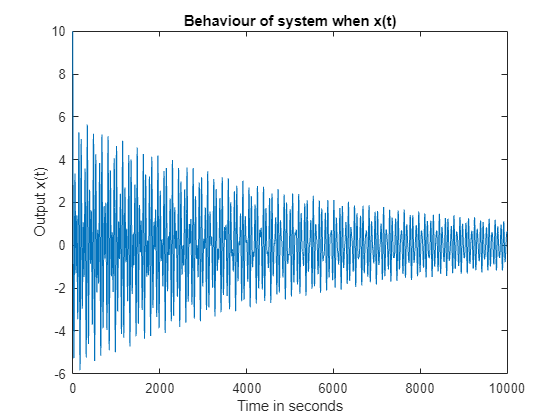


% Checking the response of system when x(t) and theta2(t) are observed 
[ts,x_dots_L3] = ode45(@(t,x)non_lin_sys3(t,x,-K*x,L3,C_03),t_span,x0_obs);
figure
plot(ts,x_dots_L3(:,1))
xlabel('Time in seconds')
ylabel('Output x(t)')
title('Behaviour of system when x(t)')

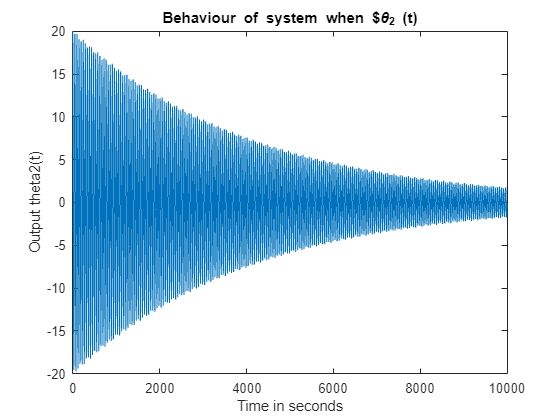

% plot(ts,x_dots_L3(:,5))

figure

plot(ts,x_dots_L3(:,5))
xlabel('Time in seconds')
ylabel('Output theta2(t)')
title('Behaviour of system when $\theta_2 (t)')

% Checking the response of system when x(t), theta1(t) and 
% theta2(t) are observed
figure

[ts,x_dots_L4] = ode45(@(t,x)non_lin_sys4(t,x,-K*x,L4,C_04),t_span,x0_obs);
figure
plot(ts,x_dots_L3(:,1))
xlabel('Time in seconds')
ylabel('Output x(t)')
title('Behaviour of system when x(t)')

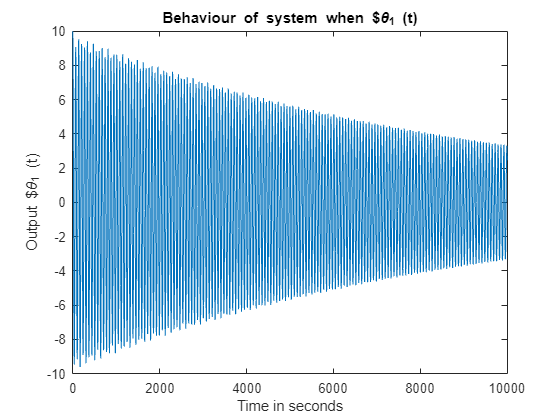

% plot(ts,x_dots_L3(:,5))

figure
plot(ts,x_dots_L3(:,3))
xlabel('Time in seconds')
ylabel('Output $\theta_1 (t)')
title('Behaviour of system when $\theta_1 (t)')

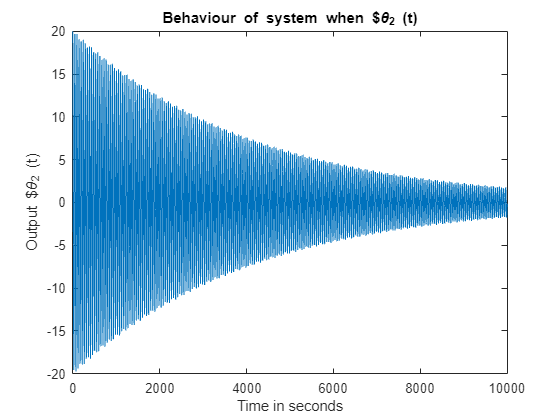


figure
plot(ts,x_dots_L3(:,5))
xlabel('Time in seconds')
ylabel('Output $\theta_2 (t)')
title('Behaviour of system when $\theta_2 (t)')

function x_dot = non_lin_sys(t,X,F,L,C)
x_dot = zeros(6,1);
% Declaring the values of system variables
M_val = 1000;
m1_val = 100;
m2_val = 100;
l1_val = 20;
l2_val = 10;
g_val = 9.81;
x = X(1);
x_d = X(2);
theta1 = X(3);
theta1_d = X(4);
theta2 = X(5);
theta2_d = X(6);
obs = L*(x-C*X);
x_dot(1) = x_d + obs(1);
x_dot(2) = (F-((m1_val*sind(theta1)*cosd(theta1))+(m2_val*sind(theta2)*cosd(theta2)))*g_val - (l1_val*m1_val*(x_dot(3)^2)*sind(theta1)) - (l2_val*m2_val*(x_dot(5)^2)*sind(theta2)))/(m1_val+m2_val+M_val-(m1_val*(cosd(theta1)^2))-(m2_val*(cosd(theta2)^2)))+obs(2);
x_dot(3) = theta1_d+obs(3);
x_dot(4) = ((cosd(theta1)*x_dot(2)-g_val*sind(theta1))/l1_val) + obs(4);
x_dot(5) = theta2_d + obs(5);
x_dot(6) = (cosd(theta2)*x_dot(2)-g_val*sind(theta2))/l2_val + obs(6);
end


function x_dot = non_lin_sys3(t,X,F,L,C)
x_dot = zeros(6,1);
% Declaring the values of system variables
M_val = 1000;
m1_val = 100;
m2_val = 100;
l1_val = 20;
l2_val = 10;
g_val = 9.81;

x = X(1);
dx = X(2);
theta1 = X(3);
theta1_d = X(4);
theta2 = X(5);
theta2_d = X(6);
y3 = [x; theta2];
sum = L*(y3-C*X);
x_dot(1) = dx + sum(1);
x_dot(2) = (F-((m1_val*sind(theta1)*cosd(theta1))+(m2_val*sind(theta2)*cosd(theta2)))*g_val - (l1_val*m1_val*(x_dot(3)^2)*sind(theta1)) - (l2_val*m2_val*(x_dot(5)^2)*sind(theta2)))/(m1_val+m2_val+M_val-(m1_val*(cosd(theta1)^2))-(m2_val*(cosd(theta2)^2)))+sum(2);
x_dot(3) = theta1_d+sum(3);
x_dot(4) = ((cosd(theta1)*x_dot(2)-g_val*sind(theta1))/l1_val) + sum(4);
x_dot(5) = theta2_d + sum(5);
x_dot(6) = (cosd(theta2)*x_dot(2)-g_val*sind(theta2))/l2_val + sum(6);
end


function x_dot = non_lin_sys4(t,X,F,L,C)
x_dot = zeros(6,1);
% Declaring the values of system variables
M_val = 1000;
m1_val = 100;
m2_val = 100;
l1_val = 20;
l2_val = 10;
g_val = 9.81;

x = X(1);
dx = X(2);
theta1 = X(3);
theta1_d = X(4);
theta2 = X(5);
theta2_d = X(6);
y4 = [x; theta1; theta2];
sum = L*(y4-C*X);
x_dot(1) = dx + sum(1);
x_dot(2) = (F-((m1_val*sind(theta1)*cosd(theta1))+(m2_val*sind(theta2)*cosd(theta2)))*g_val - (l1_val*m1_val*(x_dot(3)^2)*sind(theta1)) - (l2_val*m2_val*(x_dot(5)^2)*sind(theta2)))/(m1_val+m2_val+M_val-(m1_val*(cosd(theta1)^2))-(m2_val*(cosd(theta2)^2)))+sum(2);
x_dot(3) = theta1_d+sum(3);
x_dot(4) = ((cosd(theta1)*x_dot(2)-g_val*sind(theta1))/l1_val) + sum(4);
x_dot(5) = theta2_d + sum(5);
x_dot(6) = (cosd(theta2)*x_dot(2)-g_val*sind(theta2))/l2_val + sum(6);
end
